assert(endsWith(pwd, "\biological disk in frequency domain"), 'Not in project directory')
addpath('../../DCS_functions')

clear

#### Specimen properties

data = readmatrix('liver_properties.txt', 'CommentStyle','%');
f = data(:,1);
relative_permittivity = data(:,2);
conductivity          = data(:,3);

relative_permittivity_interpolant = griddedInterpolant(log(f),log(relative_permittivity));
conductivity_interpolant          = griddedInterpolant(log(f),log(conductivity));

relative_permittivity_func = @(f)exp(relative_permittivity_interpolant(log(f)));
conductivity_func          = @(f)exp(conductivity_interpolant(log(f)));

clear f relative_permittivity conductivity relative_permittivity_interpolant conductivity_interpolant

## Distributed Current Source

#### Electromagnet

Coil.num = 1;
Coil.inner_radius = 3.75e-3; % (m)
Coil.outer_radius = 6.00e-3; % (m)
Coil.length       = 4.00e-3; % (m)
Coil.z            = 5.00e-3; % (m)

Coil.wire_diameter = 0.35e-3; % (m)
Coil.N_turns = 60;
Coil.conductivity = 6e7; % (S/m)
Coil.series_resistance = 0; % (Ohm)

#### Sensor

Sensor.num = 10;
Sensor.side_length = 0.8e-3;

Sensor.position = [linspace(6e-3,30e-3,Sensor.num); 2.5e-3*ones(1,Sensor.num)];

#### Model

disk.radius = 30e-3; % (m)
disk.height = 6e-3; % (m)
disk.n_r = 20; % number of elements in r direction
disk.n_z = 10; % number of elements in z direction

r = linspace(0, disk.radius, disk.n_r+1);
z = linspace(-disk.height,0, disk.n_z+1);

Model = BuildModel2D('Cylinder', r,z);

build model took 0.02 seconds


clear disk r z

f = 20000;
Model.conductivity          = conductivity_func(f) * ones(1,Model.num_elms); % (S/m)
Model.relative_permittivity = relative_permittivity_func(f) * ones(1,Model.num_elms); % (1)
Model.relative_permeability = 1 * ones(1,Model.num_elms); % (1)

#### Governing equation

GoverningEquation = BuildGoveringEquation2D(Model, Coil, Sensor);

build governing equation took 6.95 seconds


#### Solve in frequency domain

V_E = readmatrix('FEA_data/V_E.csv', 'CommentStyle','%');
V_E = V_E(3);
Coil.frequency_domain.excitation = {"Voltage" V_E}; % (V)
clear V_E

% Coil.frequency_domain.excitation = {"Current" 1}; % (A)

Coil.frequency_domain.frequency = f; % (Hz)
clear f

[Model, Coil, Sensor] = SolveFrequencyDomain2D(GoverningEquation, Model, Coil, Sensor);

solve in frequency domain took 0.01 seconds


#### Plot world

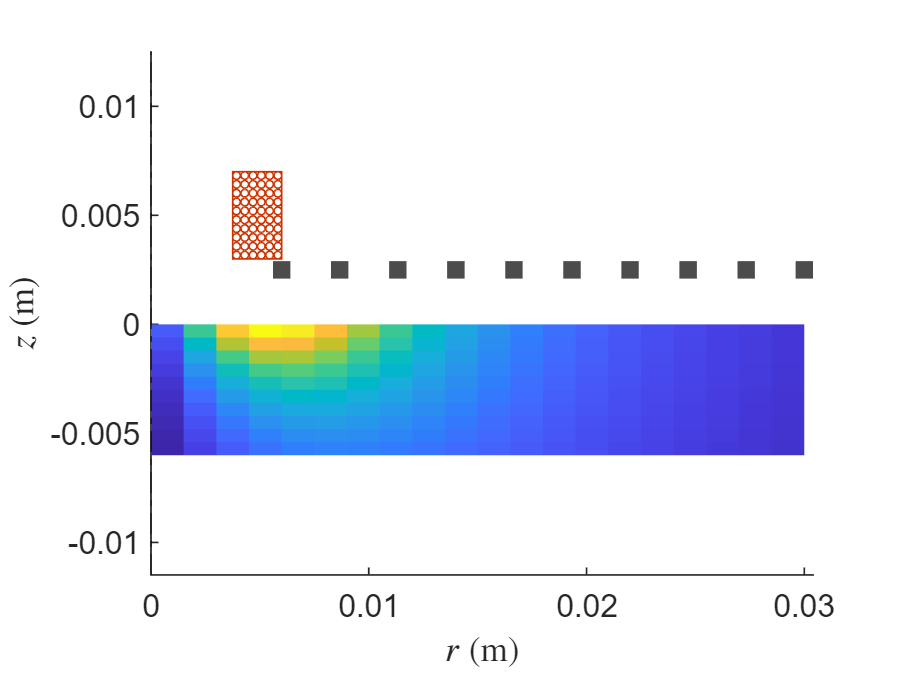

figure
PlotWorld2D(Model, Coil, Sensor, abs(Model.frequency_domain.J))

## Compare with FEA

#### Current density

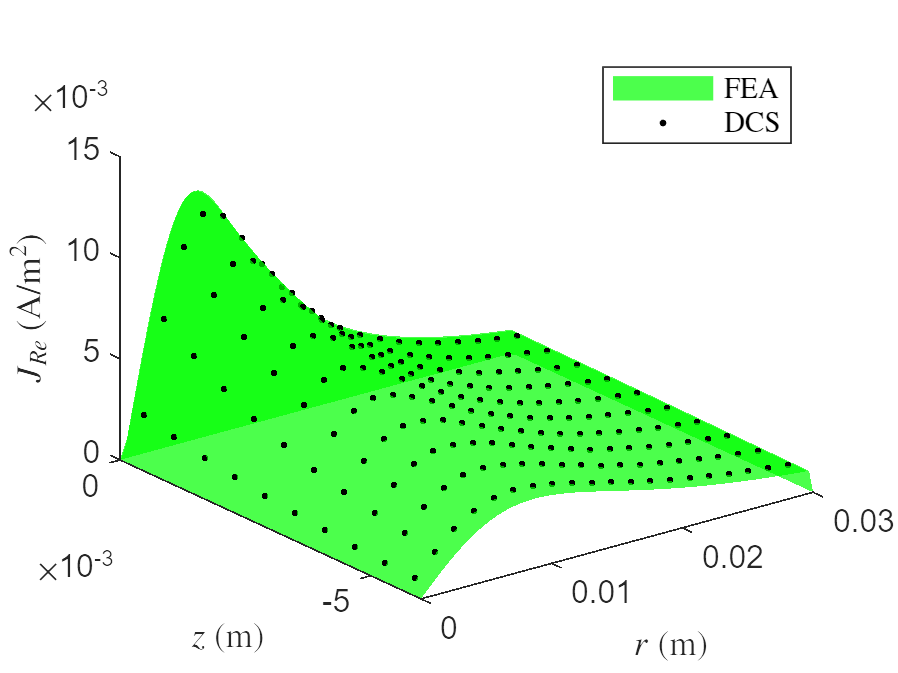

data = readmatrix('FEA_data/J.txt', 'CommentStyle','%');
FEA.r = reshape(data(:,1), 100, []);
FEA.z = reshape(data(:,2), 100, []);
FEA.J = reshape(data(:,3), 100, []);
clear data

figure
hold on
surf(FEA.r,FEA.z, real(FEA.J), 'DisplayName','FEA', 'FaceColor','g', 'FaceAlpha',0.7, 'LineStyle','none')
plot3(Model.elms_center(1,:), Model.elms_center(2,:), real(Model.frequency_domain.J), 'k.', 'DisplayName','DCS')
legend('show', 'Location','best', 'Interpreter','latex');
xlabel("$r$ (m)", 'Interpreter','latex')
ylabel("$z$ (m)", 'Interpreter','latex')
zlabel("$J_{Re}$ (A/m$^2$)", 'Interpreter','latex')
view(3)


J_FEA = interp2(FEA.r', FEA.z', real(FEA.J)', Model.elms_center(1,:), Model.elms_center(2,:));
J_DSC = real(Model.frequency_domain.J);
error = mean(abs(J_DSC - J_FEA)) /  mean(abs(J_FEA),'all');
fprintf("relative error: %f%%", error*100)

relative error: 0.585500%

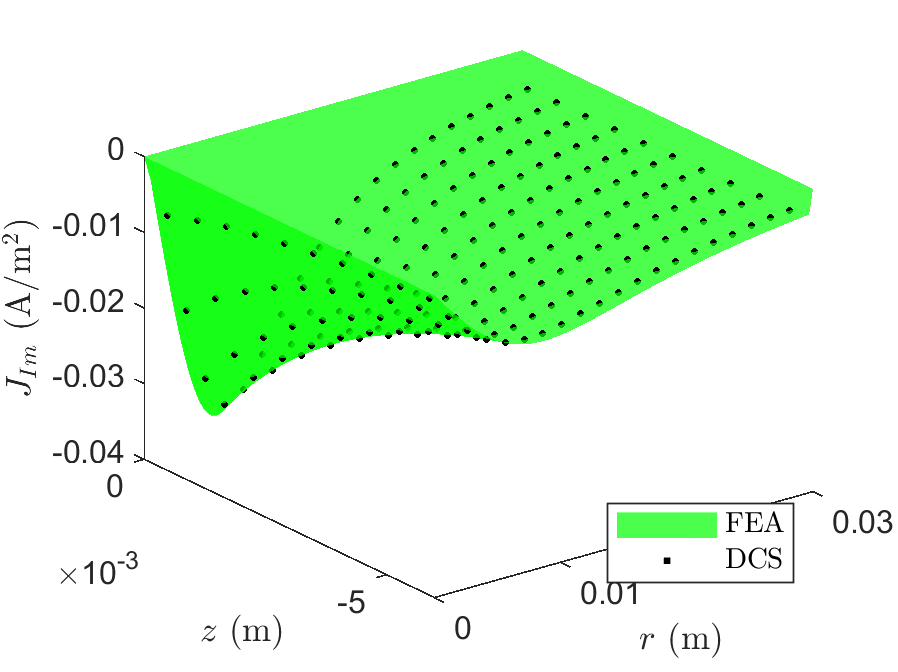


figure
hold on
surf(FEA.r,FEA.z, imag(FEA.J), 'DisplayName','FEA', 'FaceColor','g', 'FaceAlpha',0.7, 'LineStyle','none')
plot3(Model.elms_center(1,:), Model.elms_center(2,:), imag(Model.frequency_domain.J), 'k.', 'DisplayName','DCS')
legend('show', 'Location','best', 'Interpreter','latex');
xlabel("$r$ (m)", 'Interpreter','latex')
ylabel("$z$ (m)", 'Interpreter','latex')
zlabel("$J_{Im}$ (A/m$^2$)", 'Interpreter','latex')
view(3)


J_FEA = interp2(FEA.r', FEA.z', imag(FEA.J)', Model.elms_center(1,:), Model.elms_center(2,:));
J_DSC = imag(Model.frequency_domain.J);
error = mean(abs(J_DSC - J_FEA)) /  mean(abs(J_FEA),'all');
fprintf("relative error: %f%%", error*100)

relative error: 0.420928%


clear J_FEA J_DSC error

#### Magnetic flux density

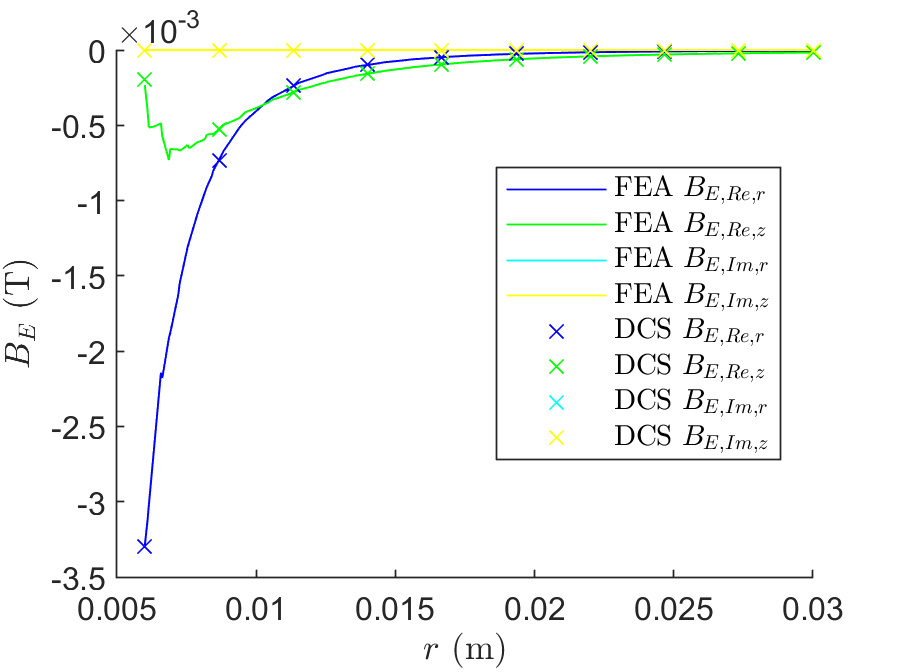

data = readmatrix('FEA_data/B.txt', 'CommentStyle','%');
FEA.r = data(:,1);
FEA.B_E_r = data(:,5);
FEA.B_E_z = data(:,6);
FEA.B_C_r = data(:,3) - FEA.B_E_r;
FEA.B_C_z = data(:,4) - FEA.B_E_z;
clear data

figure
hold on
plot(FEA.r, real(FEA.B_E_r), 'b-', 'DisplayName','FEA $B_{E,Re,r}$')
plot(FEA.r, real(FEA.B_E_z), 'g-', 'DisplayName','FEA $B_{E,Re,z}$')
plot(FEA.r, imag(FEA.B_E_r), 'c-', 'DisplayName','FEA $B_{E,Im,r}$')
plot(FEA.r, imag(FEA.B_E_z), 'y-', 'DisplayName','FEA $B_{E,Im,z}$')
plot(Sensor.position(1,:), real(Sensor.frequency_domain.B_E(1,:)), 'bx', 'DisplayName','DCS $B_{E,Re,r}$')
plot(Sensor.position(1,:), real(Sensor.frequency_domain.B_E(2,:)), 'gx' ,'DisplayName','DCS $B_{E,Re,z}$')
plot(Sensor.position(1,:), imag(Sensor.frequency_domain.B_E(1,:)), 'cx', 'DisplayName','DCS $B_{E,Im,r}$')
plot(Sensor.position(1,:), imag(Sensor.frequency_domain.B_E(2,:)), 'yx' ,'DisplayName','DCS $B_{E,Im,z}$')
legend('show', 'Location','best', 'Interpreter','latex');
xlabel("$r$ (m)", 'Interpreter','latex')
ylabel("$B_E$ (T)", 'Interpreter','latex')

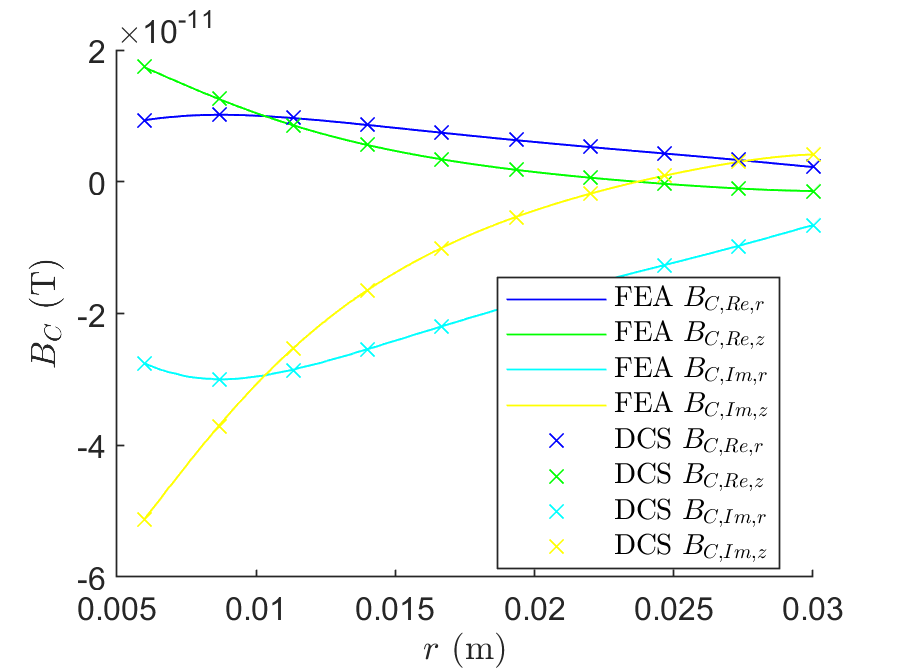


figure
hold on
plot(FEA.r, real(FEA.B_C_r), 'b-', 'DisplayName','FEA $B_{C,Re,r}$')
plot(FEA.r, real(FEA.B_C_z), 'g-', 'DisplayName','FEA $B_{C,Re,z}$')
plot(FEA.r, imag(FEA.B_C_r), 'c-', 'DisplayName','FEA $B_{C,Im,r}$')
plot(FEA.r, imag(FEA.B_C_z), 'y-', 'DisplayName','FEA $B_{C,Im,z}$')
plot(Sensor.position(1,:), real(Sensor.frequency_domain.B_C(1,:)), 'bx', 'DisplayName','DCS $B_{C,Re,r}$')
plot(Sensor.position(1,:), real(Sensor.frequency_domain.B_C(2,:)), 'gx' ,'DisplayName','DCS $B_{C,Re,z}$')
plot(Sensor.position(1,:), imag(Sensor.frequency_domain.B_C(1,:)), 'cx', 'DisplayName','DCS $B_{C,Im,r}$')
plot(Sensor.position(1,:), imag(Sensor.frequency_domain.B_C(2,:)), 'yx' ,'DisplayName','DCS $B_{C,Im,z}$')
legend('show', 'Location','best', 'Interpreter','latex');
xlabel("$r$ (m)", 'Interpreter','latex')
ylabel("$B_C$ (T)", 'Interpreter','latex')

## Frequency Sweep

#### Plot specimen properties

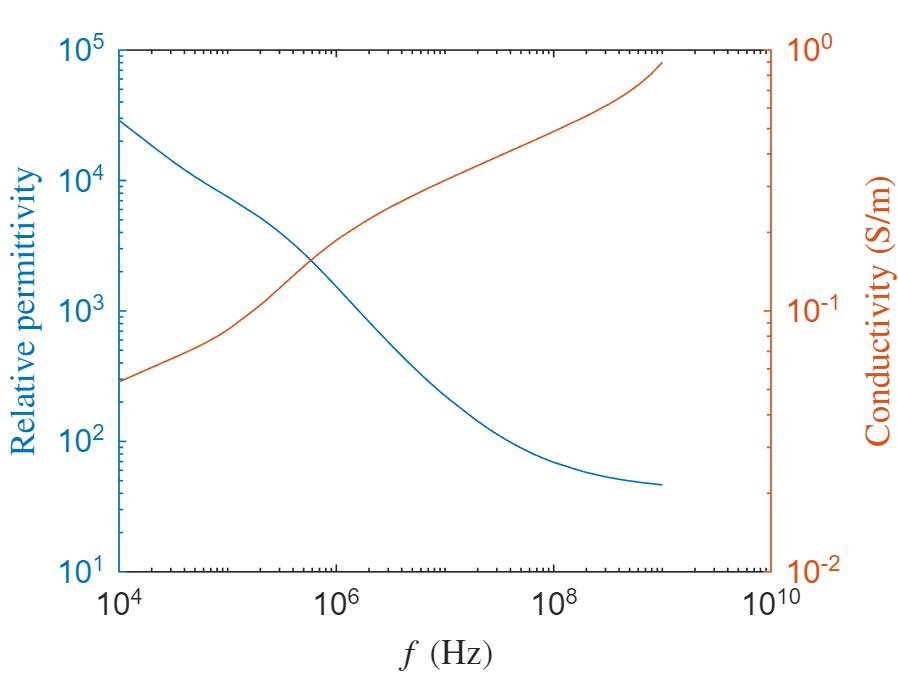

f = logspace(4, 9);

figure
yyaxis left
loglog(f, relative_permittivity_func(f))
ylabel("Relative permittivity", 'Interpreter','latex')
yyaxis right
loglog(f, conductivity_func(f))
ylabel("Conductivity (S/m)", 'Interpreter','latex')
xlabel("$f$ (Hz)", 'Interpreter','latex')

#### Magnetic flux density

B_C = zeros(2, numel(f));
for i = 1:numel(f)
    Model.conductivity          = conductivity_func(f(i))          * ones(1,Model.num_elms); % (S/m)
    Model.relative_permittivity = relative_permittivity_func(f(i)) * ones(1,Model.num_elms); % (1)
    GoverningEquation = BuildGoveringEquation2D(GoverningEquation, Model);

    [Model, Coil, Sensor] = SolveFrequencyDomain2D(GoverningEquation, Model, Coil, Sensor);
    B_C(:,i) = Sensor.frequency_domain.B_C(:,1);
end

solve in frequency domain took 0.00 seconds
solve in frequency domain took 0.00 seconds
solve in frequency domain took 0.00 seconds
solve in frequency domain took 0.00 seconds
solve in frequency domain took 0.00 seconds
solve in frequency domain took 0.00 seconds
solve in frequency domain took 0.00 seconds
solve in frequency domain took 0.00 seconds
solve in frequency domain took 0.00 seconds
solve in frequency domain took 0.00 seconds
solve in frequency domain took 0.00 seconds
solve in frequency domain took 0.00 seconds
solve in frequency domain took 0.00 seconds
solve in frequency domain took 0.00 seconds
solve in frequency domain took 0.00 seconds
solve in frequency domain took 0.00 seconds
solve in frequency domain took 0.00 seconds
solve in frequency domain took 0.00 seconds
solve in frequency domain took 0.00 seconds
solve in frequency domain took 0.00 seconds
solve in frequency domain took 0.00 seconds
solve in frequency domain took 0.00 seconds
solve in frequency domain took 0

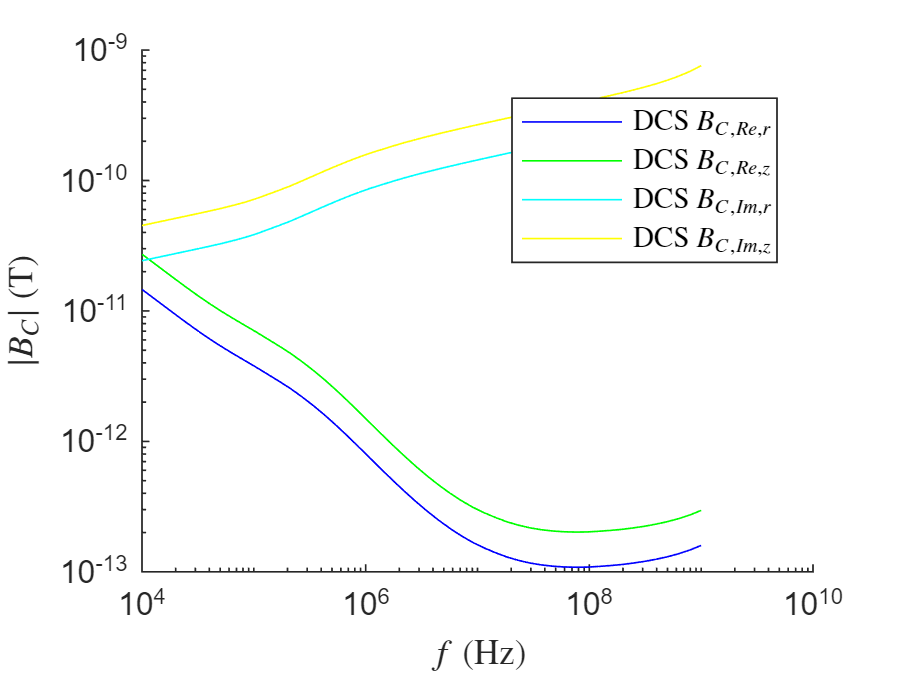


figure
hold on
plot(f, abs(real(B_C(1,:))), 'b-', 'DisplayName','DCS $B_{C,Re,r}$')
plot(f, abs(real(B_C(2,:))), 'g-' ,'DisplayName','DCS $B_{C,Re,z}$')
plot(f, abs(imag(B_C(1,:))), 'c-', 'DisplayName','DCS $B_{C,Im,r}$')
plot(f, abs(imag(B_C(2,:))), 'y-' ,'DisplayName','DCS $B_{C,Im,z}$')
legend('show', 'Location','best', 'Interpreter','latex');
xlabel("$f$ (Hz)", 'Interpreter','latex')
ylabel("$|B_C|$ (T)", 'Interpreter','latex')
set(gca, 'XScale', 'log', 'YScale', 'log')


clear f i B_C